# 频域实验

## 一、实验数据处理

读取实验室获得的频域数据

sheets=sheetnames("FrequentDomain.xlsx");
i=1;%选取俯仰通道数据进行建模
data=readmatrix("FrequentDomain.xlsx","Sheet",sheets(1));
freq=data(:,3*1-2);%原数据单位为Hz
A=data(:,3*1-1);%原数据单位为dB
P=data(:,3*1);

根据获得的频域数据，绘制频率特性曲线

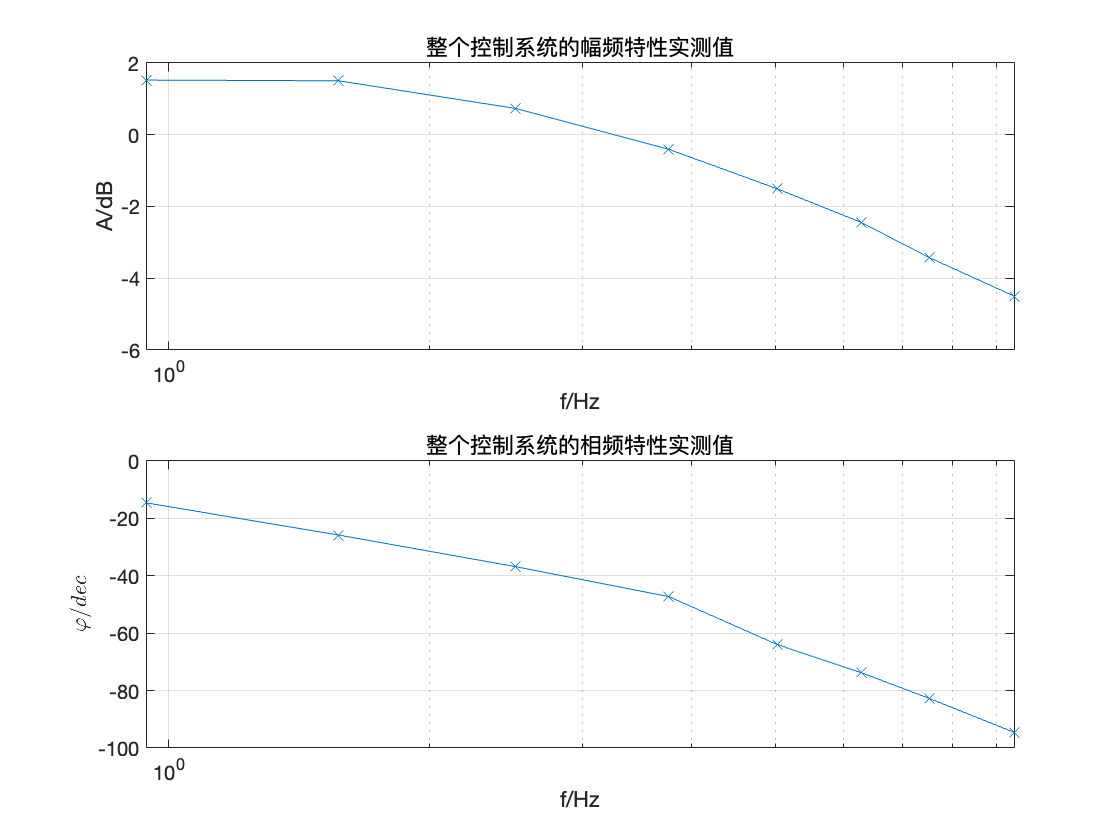

figure();
subplot(2,1,1);
semilogx(freq,A,'x-');
xlabel("f/Hz");
ylabel("A/dB");
title("整个控制系统的幅频特性实测值")
grid on
subplot(2,1,2);
semilogx(freq,P,'x-');
title("整个控制系统的相频特性实测值")
xlabel("f/Hz");
ylabel("$\varphi/dec$","Interpreter","latex")
grid on

## 二、系统辨识获取传递函数

np=[3 2];%俯仰通道可以将整个系统传递函数识别为3极点，0零点的形式
nz=[0 1];%偏航通道可以将整个系统传递函数识别为2极点，1零点的形式
A2=10.^(A./20);%将增益数据单位由dB转为1
h=A2.*exp(1i*P/180*pi);
data=idfrd(h,freq,0);
Pid=tfest(data,np(i),nz(i));
display(Pid)

Pid =
 
               2018
  -------------------------------
  s^3 + 21.6 s^2 + 448.3 s + 1634
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 0
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using TFEST on frequency response data "data".
Fit to estimation data: 93.58%                          
FPE: 0.002505, MSE: 0.0008348                           


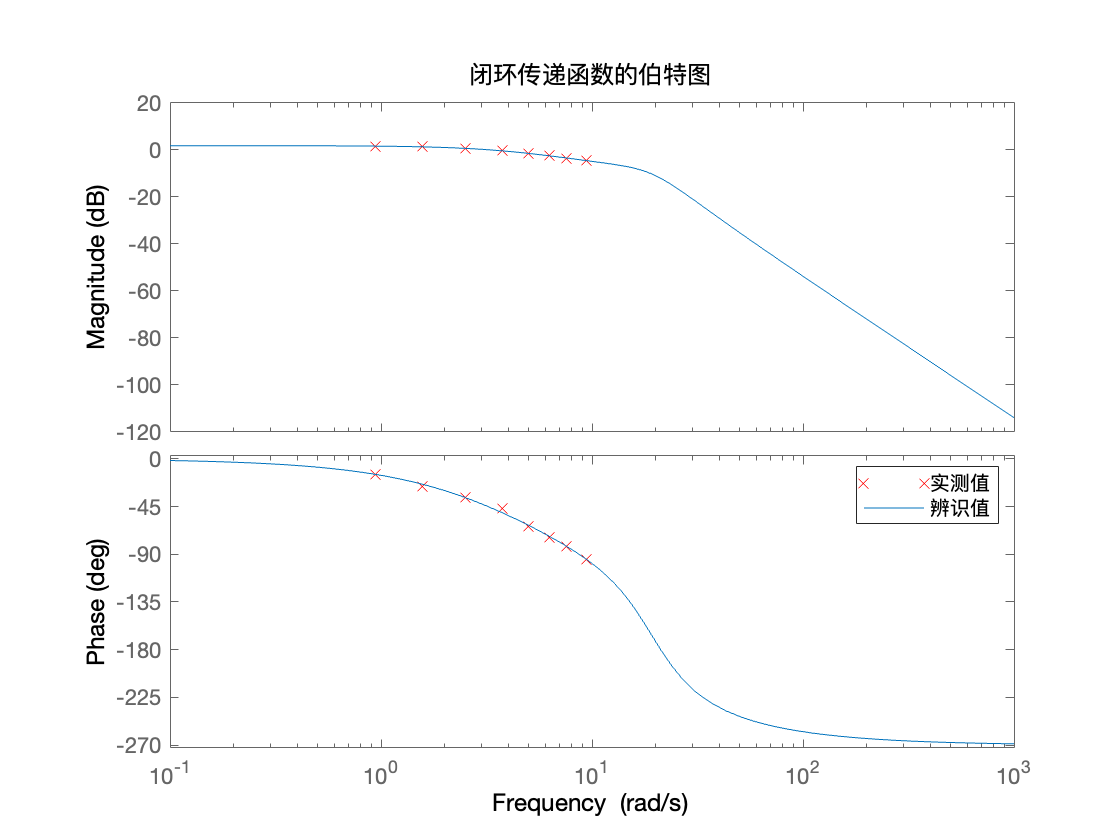

figure();
bode(data,'rx',Pid);
legend('实测值','辨识值');
title('闭环传递函数的伯特图');

## 三、频域方法判断稳定（奈奎斯特判据）

对于识别出来的改系统，其开环传递函数的正实部极点数P=1，半闭合曲线$\Gamma_{GH}$    不穿过(-1,j0)点，且逆时针包围零界点(-1,j0)点的圈数R=1，所以该系统稳定。

%反推出开环传递函数
G1=1/(1/Pid-1);
%计算正实部极点数
[p,z]=pzmap(G1);
fprintf('numbers of poles with positive real part: %d',sum(real(p)>0))

numbers of poles with positive real part: 1

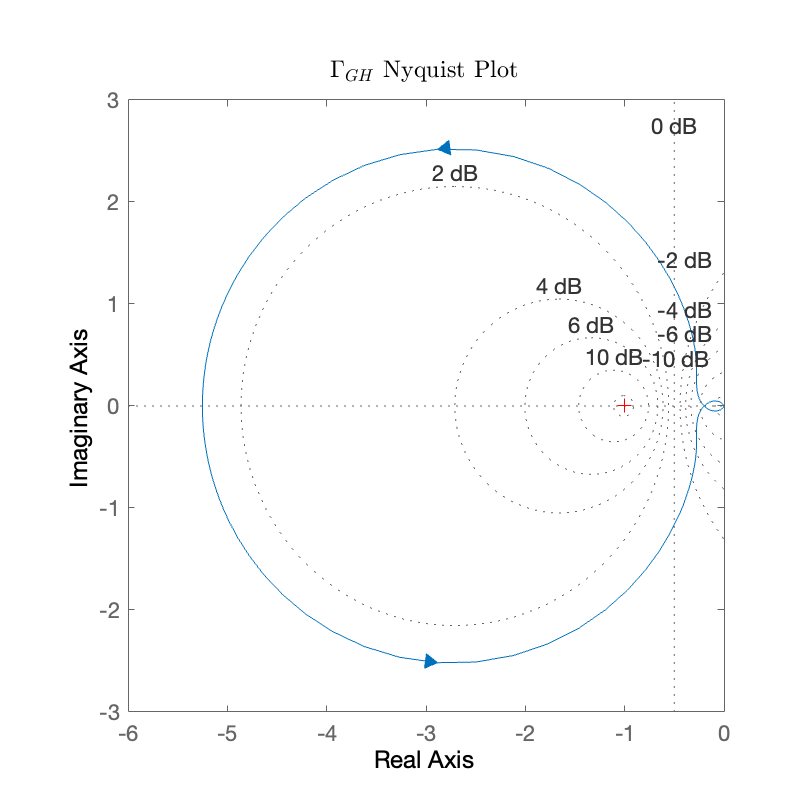

%绘制奈奎斯特曲线和开环零极点图
figure('Position',[0,0,400,400]);
nyquistplot(G1);
title('$\Gamma_{GH}$ Nyquist Plot',"Interpreter","latex")
grid on;

### 3.1计算稳定裕度

[Gm,Pm,Wcg,Wcp] = margin(G1);
Gm_dB = 20*log10(Gm);
fprintf("增益裕度Gain margin:\t%.3fdB,%.2f\n" + ...
    "相位裕度Phase margin:\t%.2f角度\n" + ...
    "截止频率Gain crossover frequency:\t%.2f\n" + ...
    "相位交界频率Phase crossover frequency:\t%.2f", ...
    Gm_dB,Gm,Pm,Wcg,Wcp);

增益裕度Gain margin:	13.955dB,4.99
相位裕度Phase margin:	67.00角度
截止频率Gain crossover frequency:	21.17
相位交界频率Phase crossover frequency:	4.33